Dati del problema 21/06/2021: 

 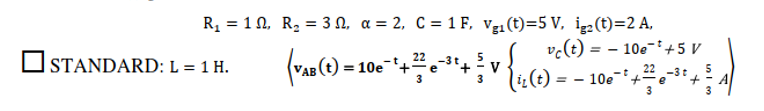

                    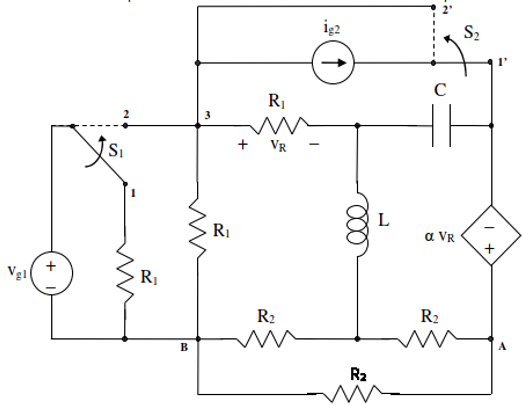

R1=1;
R2=3;
alpha=2;
C=1;
%Vg=5;
Ig=2;
L=1;
G1=1/R1;
G2=1/R1;
G3=1/R2;
G4=1/R2;
G5=1/R2;

Circuito per t<0:

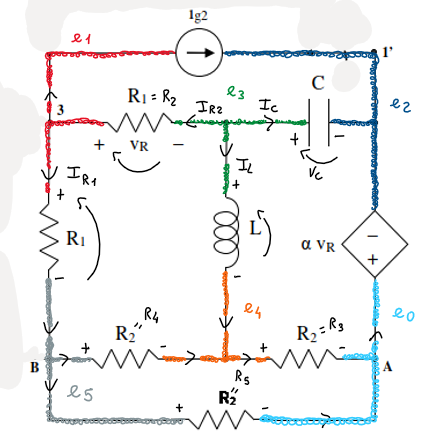

Matrice risolutiva:

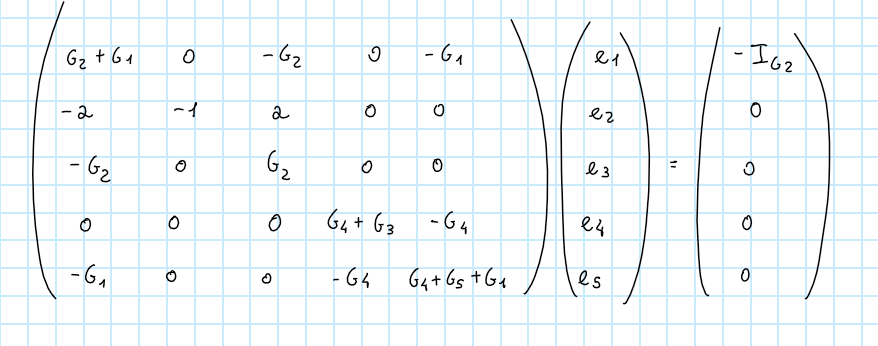

G=[G2+G1, 0, -G2, 0, -G1; 
    -alpha, -1, alpha, 0, 0;
    -G2, 0, G2, 0, 0;
    0, 0, 0, G4+G3, -G4;
    -G1, 0, 0, -G4, G4+G5+G1];
I=[-Ig; 0; 0; 0; 0];
E=G\I

E =    -6.0000
         0
   -6.0000
   -2.0000
   -4.0000


Mi ricavo $V_{\textrm{c0}}$ e $I_{\mathrm{L0}}$

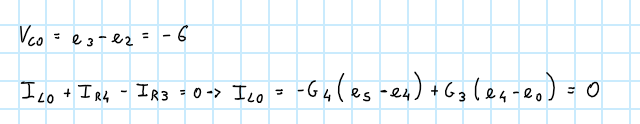

Vc0=E(3)-E(2)

Vc0 = -6.0000

Il0=-(G4*((E(5))-(E(4))))+(G3*((E(4))))

Il0 = 0

Circuito per t>0: 

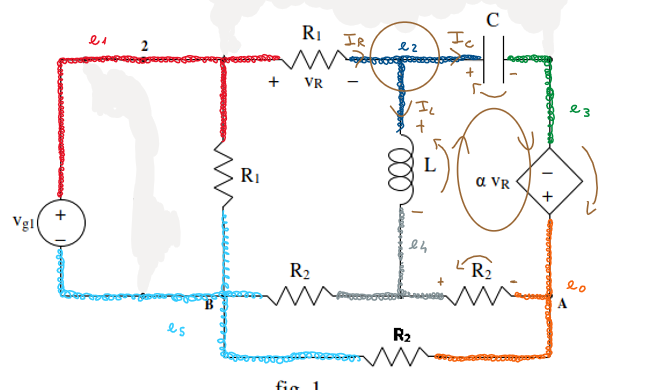

Matrice risolutiva

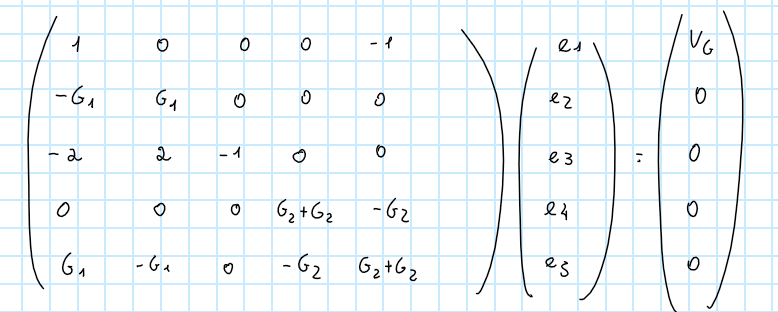

syms Vg Vc Il;
G_2=[1, 0, 0, 0, -1;
    -G1, G1, 0, 0, 0;
    -alpha, alpha, -1, 0, 0;
    0, 0, 0, G2+G2, -G2;
    G1, -G1, 0, -G2, G2+G2];
I_2=[Vg; 0; 0; 0; 0];
E_2=G_2\I_2;

Ricavo le equazioni per $V_c \left(t\right)$ e $I_l \left(t\right)$

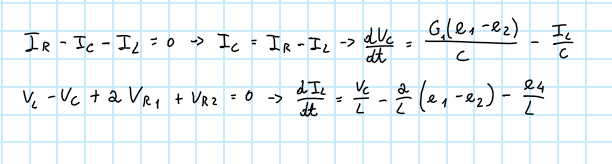

eq1=(G1*(E_2(1)-E_2(2))/C)-(Il/C)

$$eq1 = -\mathrm{Il}$$

eq2=(Vc/L)-((alpha/L)*(E_2(1)-E_2(2)))-(E_2(4)/L)

$$eq2 = \mathrm{Vc}$$

Risolvo le equazioni differenziali 

VC0 = -6; %cond. iniziali
IL0 = 0;
syms t x1(t) x2(t);
Vg  = 5;
x=[x1(t); x2(t)];
g=[Vg];
A = [0, -1;  
     1, 0];       
B = [ 0;
     0];
Dx = [diff(x1,t)== A(1,:)*x + B(1,:)*g, 
      diff(x2,t)== A(2,:)*x + B(2,:)*g];
cond_ini = [x1(0)==VC0,
            x2(0)==IL0];
S = dsolve(Dx,cond_ini);
simplify(S.x1)

$$ans = -6\,\cos\left(t\right)$$

simplify(S.x2)

$$ans = -6\,\sin\left(t\right)$$